# Example 2: Case of a suspension bridge

Computation of displacement repsonse of the vertical displacement of a suspension bridge to a random load, represented here by an uncorrelated white noise with zero mean.

## Geometry definition

The modal properties of the single span suspension bridge are imported. THe variable 'wn' is the circular eigen-frequency and "phi" is the vector of mode-shapes

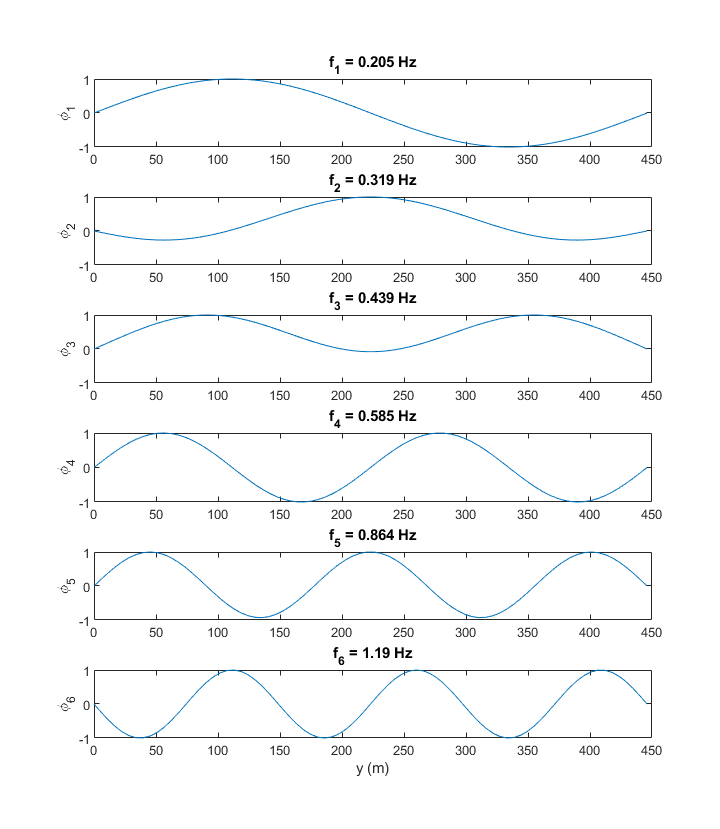

clearvars;close all;clc;

load('bridgeModalProperties.mat','wn','phi')
Nmodes = 6;  % number of eigen modes of interest
phi = phi(1:Nmodes,:);
wn = wn(1:Nmodes);
Nnodes = size(phi,2);
y = linspace(0,446,Nnodes); % span length discretized in Nnodes nodes


figure('position',[560   285   576   663])
for ii=1:Nmodes,
    subplot(Nmodes,1,ii)
    box on;grid on
    plot(y,phi(ii,:));
    ylabel(['\phi_',num2str(ii)])
    title(['f_',num2str(ii),' = ',num2str(wn(ii)/2/pi,3),' Hz']); 
    ylim([-1,1])

end
set(gcf,'color','w')
    xlabel('y (m)');

## Computation of the displacement response in the time domain

N = 12000;
fs = 15;
dt = 1/fs;
t = [0:N-1].*dt;
fprintf(['total duration is ',num2str(t(end),4),' s \n'])

total duration is 799.9 s 


m = 6166; % mass of the bridge deck per meter (kg/m)
Fy = 200.*randn(Nnodes,N); % Force normal to the bridge deck
zetaStruct = 5e-3*ones(Nmodes,1); % Modal damping ratios taken as 0.5 % for every mode

tic
[Do1] = dynaResp_TD(m,y,phi,wn,zetaStruct,Fy,t,'method','Newmark');
toc

Elapsed time is 1.767386 seconds.



tic
[Do2] = dynaResp_TD(m,y,phi,wn,zetaStruct,Fy,t,'method','RK4');
toc

Elapsed time is 1.285151 seconds.


## Time series comparison

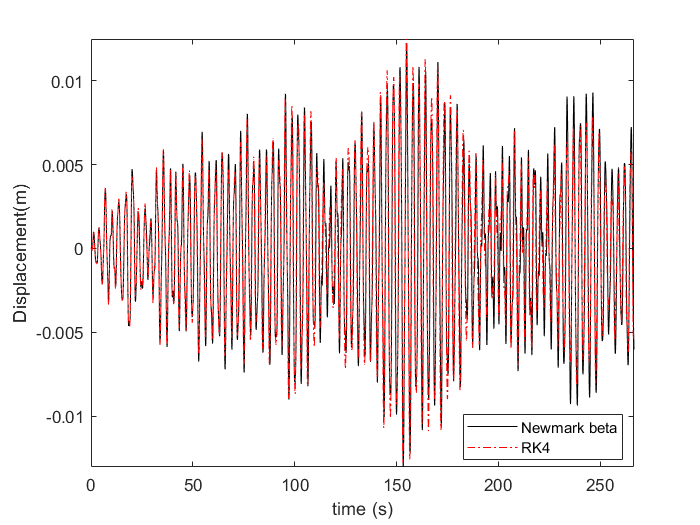


indMax = 4000; % indice corresponding tot he last time step included in the plot
clf;close all;
figure
plot(t(1:indMax),Do1(round(Nnodes/2),1:indMax),'k',t(1:indMax),Do2(round(Nnodes/2),1:indMax),'r-.');
xlabel('time (s)')
ylabel('Displacement(m)')
axis tight
set(gcf,'color','w')
legend('Newmark beta','RK4','location','best')

## PSD  displacement comparison

The plot of the PSD shows that the RK4 method tends to respect the eigenfrequencies used as input, but as the mode number increases, the damping is not properly represented. On the other hand, the newmark-beta method provides good damping estimates but the eigenfrequencies are biased toward lower values  as the mode number increases.

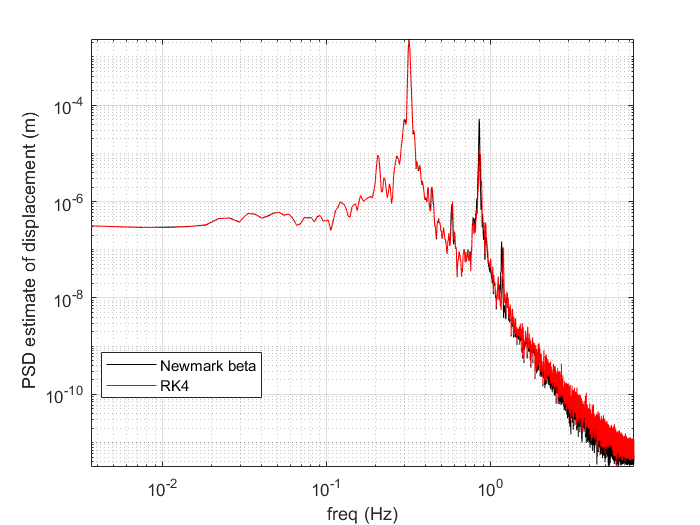

% 
[S1,f]=pwelch(Do1(round(Nnodes/2),:),[],[],[],fs);
[S2,f]=pwelch(Do2(round(Nnodes/2),:),[],[],[],fs);

clf;close all;
figure
loglog(f,S1,'k',f,S2,'r');

xlabel('freq (Hz)')
ylabel(' PSD estimate of displacement (m)')
axis tight
set(gcf,'color','w')
legend('Newmark beta','RK4','location','best')
grid on
grid minor